# Loading the Filters

load Hd;
load beamforming_hw_correction_coeffs.mat;

# Reading one file to get parameters

folder = 'Female Voice 90deg 60dBA Noise 180deg 60dBA';
filename = [folder filesep 'Micro 1_001.wav'];
% reading one audio file
[y, Fs] = audioread(filename)

y =    -0.0002
   -0.0000
    0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0009
    0.0013
    0.0016


Fs = 48000


% size of the Samples
sizeArray = length(y);
% Number of microphones
N_mic = 16;
% zero array of size
% % (nb_Samples, nb_Micros)
sigArray = zeros(sizeArray, N_mic);

# Reading all files

for i = 1:N_mic 
    [y,Fs] = audioread(sprintf([folder filesep 'Micro %d_001.wav'], i));
    sigArray(:, i) = y;
end
sigArray

sigArray =    -0.0002    0.0004   -0.0015   -0.0013   -0.0015   -0.0031   -0.0003    0.0008    0.0001    0.0010    0.0003    0.0003   -0.0002   -0.0011   -0.0022   -0.0002
   -0.0000    0.0004   -0.0014   -0.0009   -0.0021   -0.0030   -0.0003    0.0010    0.0002    0.0012   -0.0003    0.0005   -0.0004   -0.0007   -0.0022   -0.0000
    0.0001    0.0004   -0.0012   -0.0008   -0.0027   -0.0028   -0.0004    0.0010    0.0004    0.0011   -0.0007    0.0008   -0.0005   -0.0003   -0.0022   -0.0000
    0.0003    0.0003   -0.0010   -0.0007   -0.0031   -0.0024   -0.0006    0.0008    0.0005    0.0009   -0.0010    0.0011   -0.0006    0.0002   -0.0022   -0.0002
    0.0004    0.0001   -0.0008   -0.0009   -0.0034   -0.0019   -0.0009    0.0004    0.0006    0.0006   -0.0012    0.0015   -0.0007    0.0005   -0.0022   -0.0005
    0.0005    0.0000   -0.0006   -0.0009   -0.0034   -0.0014   -0.0013    0.0001    0.0006    0.0003   -0.0012    0.0017   -0.0007    0.0008   -0.0021   -0.0009
    0.0007   -0.0001   

# Calculating the Correction Coefficients

Y_ref_rms = rms(y(Fs : end)); % Fs:end to jump first second(transient)
MAT_rms = rms(sigArray(Fs:end, :)); % sigArray(rows, cols)

correct_coeffs = MAT_rms.^(-1).* Y_ref_rms; 
% .* Element-wise multiplication
% .^ Element-wise power

% saving the correction coeffs as CORRECT_COEFFS
% save beamforming_hw_correction_coeffs correct_coeffs

# Correcting the Signal

% the entire signal corrected
sigCorrected = zeros(sizeArray, N_mic);

for i = 1:N_mic
    sigCorrected(:, i) = sigArray(:, i) * correct_coeffs(i);
end

# Ploting figures

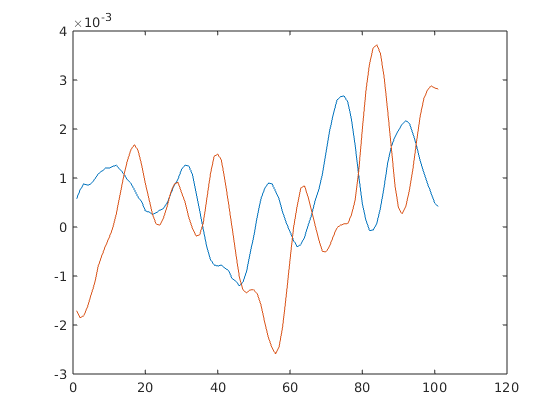

% figure(1)
% plot(y(Fs: Fs+100, :))
figure(2)
plot( sigArray(Fs: Fs+100, 7:8))

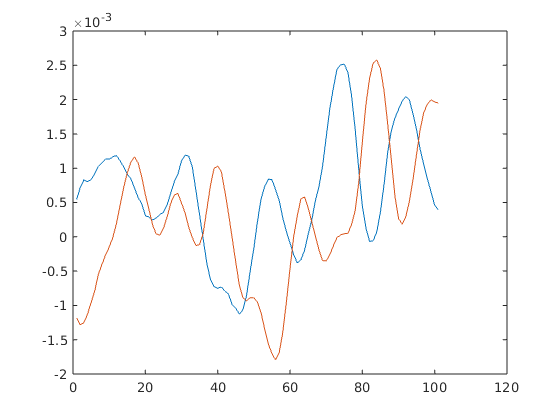

figure(3)
plot( sigCorrected(Fs: Fs+100, 7:8))

# Filtering

filtered = filter(Hd, sigCorrected);
filtered

filtered =    -0.0003    0.0009   -0.0028   -0.0024   -0.0032   -0.0064   -0.0006    0.0012    0.0002    0.0022    0.0006    0.0006   -0.0004   -0.0025   -0.0050   -0.0004
    0.0002    0.0001    0.0001    0.0006   -0.0014   -0.0002   -0.0001    0.0004    0.0003    0.0005   -0.0012    0.0007   -0.0006    0.0007   -0.0002    0.0003
    0.0015   -0.0035    0.0106    0.0092    0.0105    0.0242    0.0019   -0.0043   -0.0004   -0.0084   -0.0033   -0.0016    0.0012    0.0104    0.0184    0.0015
    0.0030   -0.0100    0.0287    0.0230    0.0367    0.0675    0.0060   -0.0140   -0.0029   -0.0252   -0.0031   -0.0081    0.0064    0.0247    0.0521    0.0028
    0.0035   -0.0185    0.0521    0.0400    0.0798    0.1255    0.0127   -0.0279   -0.0083   -0.0484    0.0028   -0.0212    0.0157    0.0388    0.0992    0.0044
    0.0021   -0.0273    0.0769    0.0587    0.1388    0.1893    0.0227   -0.0432   -0.0170   -0.0742    0.0164   -0.0426    0.0293    0.0478    0.1550    0.0071
   -0.0020   -0.0344   

# Sum up and Writedown the Filtered and corrected audio file

% result = zeros(N_mic, 1);

for i=1:sizeArray
    result(i) = sum(filtered(i, :));
end

audiowrite('./CorrFil_all.wav', 200 * result, Fs)

# Doing beamforming

% required to shifted the audio data according to the delay and the
% microphone distance
delay= zeros(1,N_mic);
filtered_z = filtered;

phi = pi/2;
d = 0.07;
c = 340;

for i=1:16
    delay(1,i)= d*i*cos(phi)/c;
end
shifted_z = zeros(sizeArray, N_mic);
for i=1:8
    shifted_z(:,i) = delayseq(filtered_z(:,i), -delay(1,8)/2 + (i-8)*delay(1,i));
end

for i=9:16
    shifted_z(:, i) = delayseq(filtered_z(:,i), +delay(1,9)/2 + (i-9)*delay(1,i));
end
shifted_z

shifted_z =    -0.0003    0.0009   -0.0028   -0.0024   -0.0032   -0.0064   -0.0006    0.0012    0.0002    0.0022    0.0006    0.0006   -0.0004   -0.0025   -0.0050   -0.0004
    0.0002    0.0001    0.0001    0.0006   -0.0014   -0.0002   -0.0001    0.0004    0.0003    0.0005   -0.0012    0.0007   -0.0006    0.0007   -0.0002    0.0003
    0.0015   -0.0035    0.0106    0.0092    0.0105    0.0242    0.0019   -0.0043   -0.0004   -0.0084   -0.0033   -0.0016    0.0012    0.0104    0.0184    0.0015
    0.0030   -0.0100    0.0287    0.0230    0.0367    0.0675    0.0060   -0.0140   -0.0029   -0.0252   -0.0031   -0.0081    0.0064    0.0247    0.0521    0.0028
    0.0035   -0.0185    0.0521    0.0400    0.0798    0.1255    0.0127   -0.0279   -0.0083   -0.0484    0.0028   -0.0212    0.0157    0.0388    0.0992    0.0044
    0.0021   -0.0273    0.0769    0.0587    0.1388    0.1893    0.0227   -0.0432   -0.0170   -0.0742    0.0164   -0.0426    0.0293    0.0478    0.1550    0.0071
   -0.0020   -0.0344  

mic = phased.OmnidirectionalMicrophoneElement('FrequencyRange',[20 20e3])

mic =   phased.OmnidirectionalMicrophoneElement with properties:

    FrequencyRange: [20 20000]
       BackBaffled: false



arr_microphones = phased.ULA('NumElements', 16, 'ElementSpacing', 0.07, 'ArrayAxis','x',...
    'Element', mic)

arr_microphones =   phased.ULA with properties:

           Element: [1×1 phased.OmnidirectionalMicrophoneElement]
       NumElements: 16
    ElementSpacing: 0.0700
         ArrayAxis: 'x'
             Taper: 1



ang = [90; 0];   % 1st for azimuth, 2nd for elevation *in degrees..
                    
c = 340;

beamformer = phased.TimeDelayBeamformer('SensorArray', arr_microphones,...
    'SampleRate', Fs,'PropagationSpeed',c,...
    'Direction', ang);

out_audio = beamformer(shifted_z)

out_audio =    -0.0114
    0.0001
    0.0424
    0.1172
    0.2190
    0.3374
    0.4576
    0.5640
    0.6423
    0.6822


audiowrite('./Beamformed_90_dgr.wav', 200 * out_audio, Fs)